format long;
clear;
addpath(genpath('../'))
load f12_1_200.mat
kk = 0.5:0.5:100;
k = kk;
w_index = find_sign_change(F12);
w = w_index*0.0002;

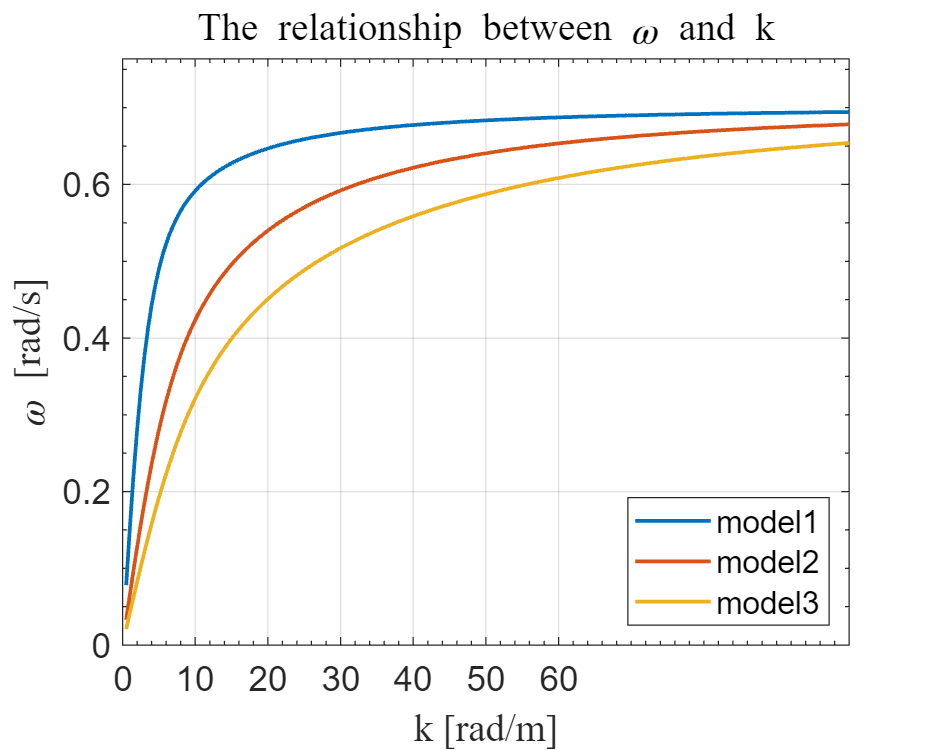

% load dispersion_relation.mat
figure(1)
i = 1:20000;
mean_w = w;
k = kk;
p = plot(k, mean_w(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, max(w(:))*1.1])
yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('\omega [rad/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between \omega and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');
set(gcf, 'Position', [100, 100, 500, 400]);

                                                                                        
$$\textbf{相速度：}c_p = \frac{\omega(k)}{k} \\
\textbf{群速度：}c_g = \frac{d\omega(k)}{dk}$$


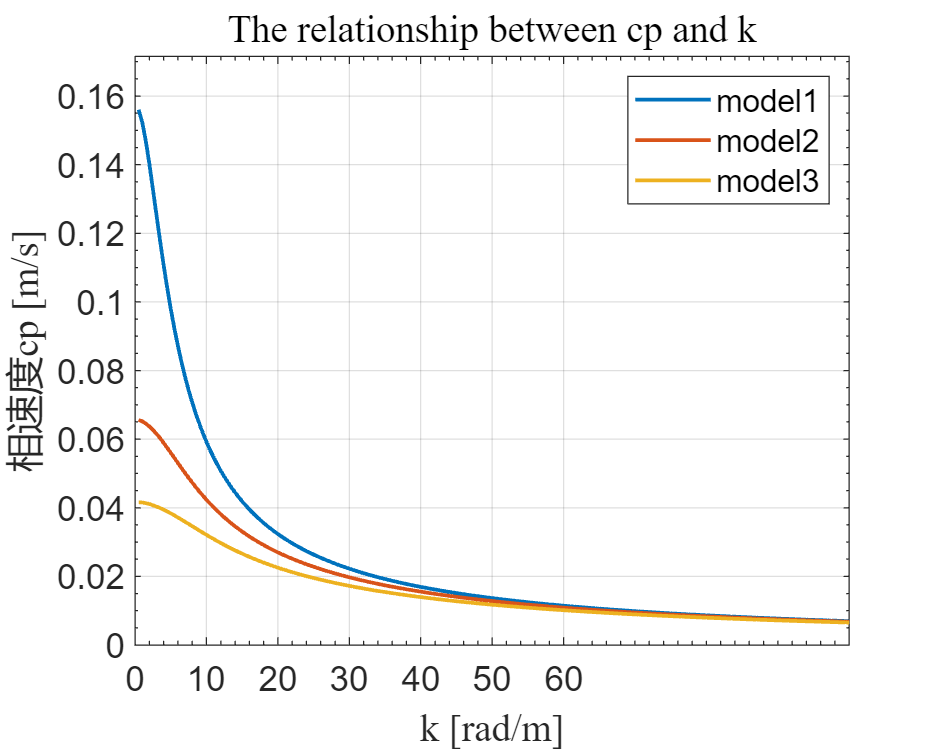

% 计算群速度和相速度
cp = mean_w./k';
cg = diff(mean_w)/0.5;

figure(2)
p = plot(k, cp(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cp(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('相速度cp [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cp and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');

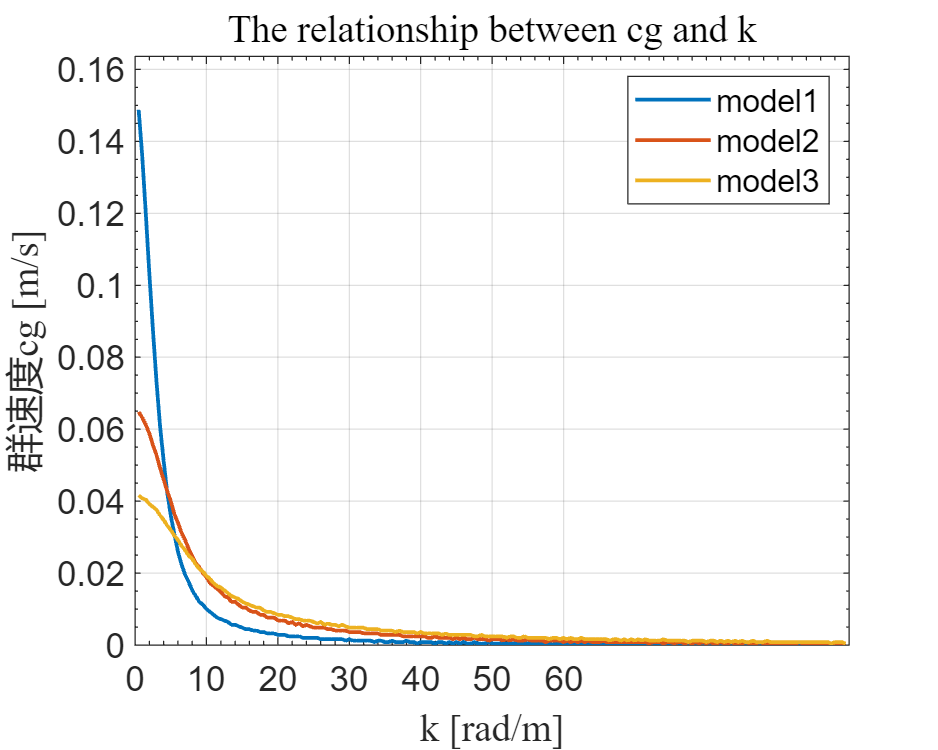

set(gcf, 'Position', [100, 100, 500, 400]);

figure(3)
p = plot(k(1:end-1), cg(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');

xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cg(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('群速度cg [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cg and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');

set(gcf, 'Position', [100, 100, 500, 400]);

拟合直线求$c_{p0}$

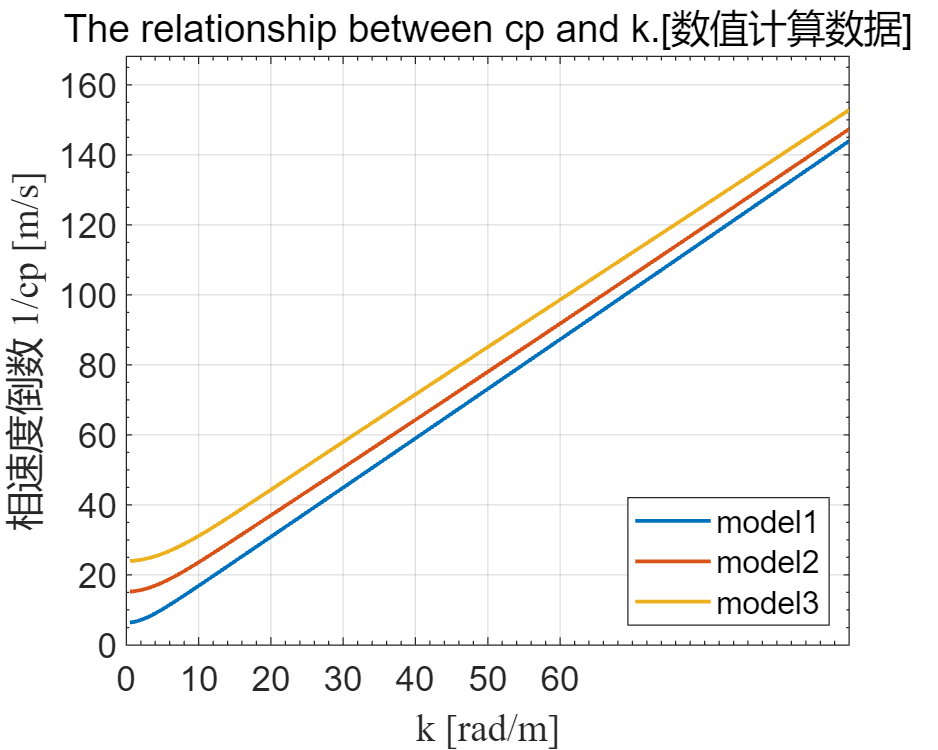

cp_prime = 1./cp;
figure(4)
p = plot(k', cp_prime(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cp_prime(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('相速度倒数 1/cp [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cp and k.[数值计算数据]', 'FontSize', 14);
legend('model1', 'model2', 'model3', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');

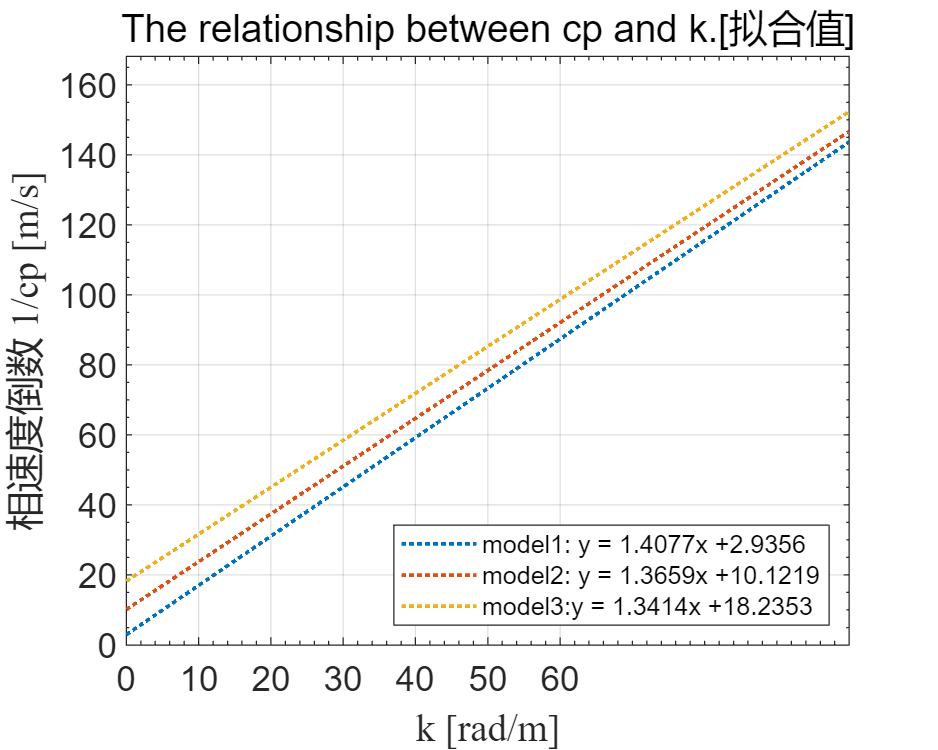

set(gcf, 'Position', [100, 100, 500, 400]);


figure(5)
% 利用计算数据提取cp0，用于后面论文《On the dispersion relation for trapped internal waves》给的公式的绘制
for i =1:3
    coef_cp_prime_polyfit(:,i) = polyfit(k',cp_prime(:,i),1);
    cp_prime_polyfit(:,i) = polyval(coef_cp_prime_polyfit(:,i),[0,k]);
end
p = plot([0,k]',cp_prime_polyfit);
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = ':';

p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = ':';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = ':';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cp_prime(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('相速度倒数 1/cp [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cp and k.[拟合值]', 'FontSize', 14);
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');
set(gcf, 'Position', [100, 100, 500, 400]);
lgd_str(1) = "model1: y = " + num2str(round(coef_cp_prime_polyfit(1,1),4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,1),4));
lgd_str(2) = "model2: y = " + num2str(round(coef_cp_prime_polyfit(1,2),4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,2),4));
lgd_str(3) = "model3:y = " + num2str(round(coef_cp_prime_polyfit(1,3),4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,3),4));
legend(lgd_str,'Location','southeast','FontSize',10);

取 $N_{max} = 0.16 [ rad/s ]$

色散关系$\omega(k) = \frac{c_{p0}k}{1+\frac{c_{p0}k}{N_{max}}}$，$\frac{1}{c_{p}} = \frac{k}{N_{max}} + \frac{1}{c_{p0}}$见论文《On the dispersion relation for trapped internal waves》《The generation of internal waves by a towed sphere and its wake in a thermocline》

由图（5）拟合值，可知 对应三模态的$c_{p0} = $ 0.1833 0.0459 0.0270

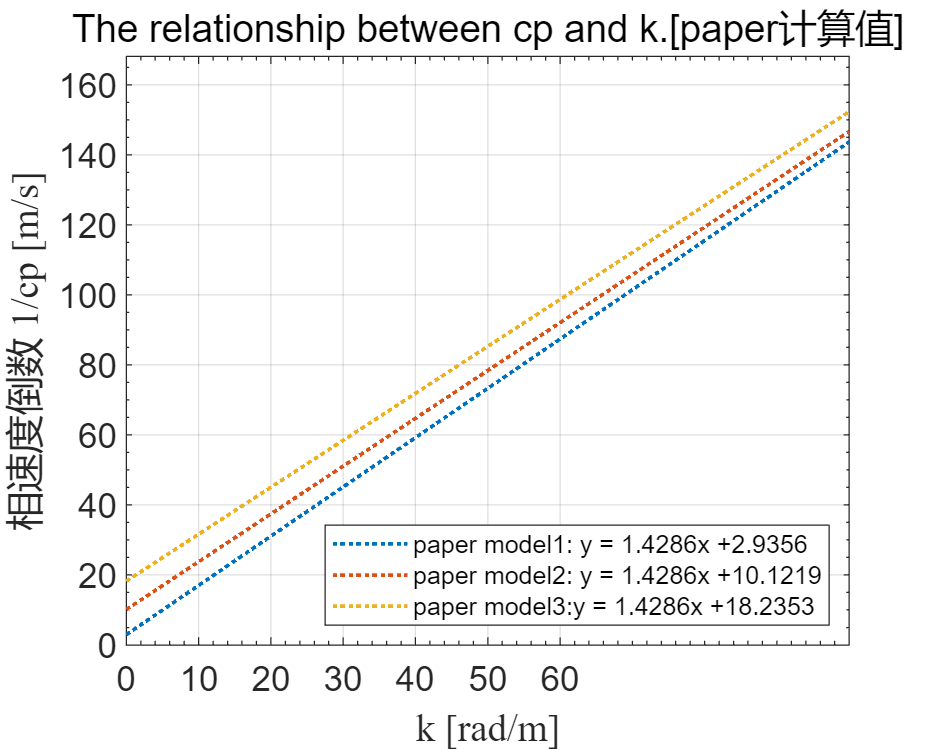

load ../../函数产生NV频率/Np.mat;
N_max = max(Np);
% 按照论文的公式，绘制色散曲线和群速度曲线
cp_paper_prime = k'/N_max + coef_cp_prime_polyfit(2,:);
figure(6)
p = plot([0,k]',cp_prime_polyfit);
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = ':';

p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = ':';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = ':';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xticks(0:10:65) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cp_prime(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('相速度倒数 1/cp [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cp and k.[paper计算值]', 'FontSize', 14);
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');
set(gcf, 'Position', [100, 100, 500, 400]);
lgd_str(1) = "paper model1: y = " + num2str(round(1/N_max,4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,1),4));
lgd_str(2) = "paper model2: y = " + num2str(round(1/N_max,4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,2),4));
lgd_str(3) = "paper model3:y = " + num2str(round(1/N_max,4)) + "x +" + num2str(round(coef_cp_prime_polyfit(2,3),4));
legend(lgd_str,'Location','southeast','FontSize',10);


figure(7)
% 按照两篇论文中提到的色散关系公式进行计算，并进行绘图对比
w_paper = k'./cp_paper_prime;
p = plot(k',[w,w_paper]);
set(p(1),   'LineStyle',    '-',    'LineWidth',    1.5,'Marker',   'o',        'MarkerSize',   2);
set(p(2),   'LineStyle',    '-',    'LineWidth',    1.5,'Marker',   'square',   'MarkerSize',   2);
set(p(3),   'LineStyle',    '-',    'LineWidth',    1.5,'Marker',   'v',        'MarkerSize',   2);
set(p(4),   'LineStyle',    '--',   'LineWidth',    1.5,'Marker',   'o',        'MarkerSize',   2);
set(p(5),   'LineStyle',    '--',   'LineWidth',    1.5,'Marker',   'square',   'MarkerSize',   2);
set(p(6),   'LineStyle',    '--',   'LineWidth',    1.5,'Marker',   'v',        'MarkerSize',   2);
xticks(0:10:65);
ylim([0,1.1*max(w_paper(:))]);
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
ylabel('\omega [rad/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between \omega and k.[数值计算 Vs paper]', 'FontSize', 14);
grid on;
legend('model1','model2','model3','model1*','model2*','model3*')
hold off


驻相线


$$\omega(k) = \frac{c_{p0}k}{1+\frac{c_{p0}k}{N_{max}}}$$



$$
x=\frac{\varphi U\left(1-c_{p m} c_{g m} / U^2\right)}{k\left(c_{p m}-c_{g m}\right)}, \quad y=\frac{\varphi c_{g m} \sqrt{\left(1-c_{p m}^2 / U^2\right)}}{k\left(c_{p m}-c_{g m}\right)}$$


% 由相速度拟合出的数据，计原色散关系和群速度
k = [0,kk]'; 

w_by_cp_polyfit = k./(coef_cp_prime_polyfit(2,:) + k*coef_cp_prime_polyfit(1,:));

cp_polyfit = 1./cp_prime_polyfit;
cg_polyfit = diff(w_by_cp_polyfit)/0.5;
cp_polyfit = cp_polyfit(1:end-1,:);



U = 0.17;

k = kk';
for i = 1:10
    phi = 2*pi*i;
    x(:,:,i) = phi*U.*(1-cp_polyfit.*cg_polyfit./U^2)./(k.*(cp_polyfit-cg_polyfit));
    y(:,:,i) = phi*cg_polyfit.*sqrt(1-cp_polyfit.^2/U^2)./(k.*(cp_polyfit-cg_polyfit));
end
y = (y + conj(y))*0.5;
temp = y(:,:,1);
index = sum(temp(:,1)==0)+1;
x = x(index:end,:,:);
y = y(index:end,:,:);

figure(8)
hold on;

for i = 1:6
plot(x(:,1,i),real(y(:,1,i)),'Color','b','LineStyle','-');
plot(x(:,1,i),-real(y(:,1,i)),'Color','b','LineStyle','-');
plot(x(:,2,i),real(y(:,2,i)),'Color','r','LineStyle','-');
plot(x(:,2,i),-real(y(:,2,i)),'Color','r','LineStyle','-');
plot(x(:,3,i),real(y(:,3,i)),'Color','g','LineStyle','-');
plot(x(:,3,i),-real(y(:,3,i)),'Color','g','LineStyle','-');
xlim([0,max(x(:,1,6))])
ylim([-max(x(:,1,6))*0.5,max(x(:,1,5))*0.6])
end
hold off

xlim([0.5 14.7])
ylim([-6.7 7.5])


k = (0:0.5:100)';
cp =  [k,1./cp_prime_polyfit];
save("cp.mat","cp");